## **Macroeconometrics Project**

### **Summary**

#### **Motivation:**

The purpose of this course is to get a theoretical and practical understanding of empirical methods for business cycle analysis and forecasting. The two main classes of models used for this purpose in research and policy environments alike are the Dynamic Factor Model (DFM) and Vector Autoregressions (VAR). Accordingly, I aim to conduct a simple exercise where I compare the forecasting performance of these two popular models for the real GDP growth of the euro area. In particular, I will use similar versions of the models where I have mixed frequencies (i.e., quarterly and monthly) and an unbalanced panel of data (i.e., ragged edges). Further, I specify the same small-to-medium-size model (between 6 and15 variables) for both models and perform estimation using Bayesian techniques. The models will be similar in spirit to Camacho and Perez-Quiros (2010) for the DFM and to Schorfheide and Song (2015) for the VAR. 

The analysis will consist of providing point and density forecasts (i.e., median and  percentiles of the posterior distribution) for the euro area real GDP growth over the short term. Then, I will contrast the forecasting ability of these two models by comparing them with the [ECB official macroeconomic projections](https://www.ecb.europa.eu/pub/projections/html/ecb.projections202312_eurosystemstaff~9a39ab5088.en.html#toc2) for the euro area growth (December 2023 BMPE and March 2024 MPE). Finally, I will compare the in-sample forecast performance of the models (compare the RMSE). This exercise will shed light on whether there are relevant differences between the DFMs and VARs in terms of forecasting and whether they are able to provide similar growth forecasting profiles as the ones from professional models used in the ECB to conduct macroeconomic projections.

#### Scope:

**Target** 

- Euro area real GDP growth 

**Models **

- Mixed-frequency Bayesian DFM with unbalanced panel

- Mixed-frequency Bayesian VAR with unbalanced panel 

**Analysis**

- Point and density forecasts of target variable

- Comparison to ECB Dec-2023 BMPE and Mar-2024 MPE

- Forecast performance comparison between models (in-sample, RMSE metric)

*References*

Camacho, Maximo, and Gabriel Perez‐Quiros. "Introducing the euro‐sting: Short‐term indicator of euro area growth." Journal of Applied Econometrics 25, no. 4 (2010): 663-694.

Schorfheide, Frank, and Dongho Song. "Real-time forecasting with a mixed-frequency VAR." Journal of Business & Economic Statistics 33, no. 3 (2015): 366-380.

**@Erik Andres Escayola**

### `Main script`

`Data description`

`(Mnemonic -> Variable - Sector - Type - Frequency)`

`1  GDP -> Real GDP - Activity - Hard - Q	`

`2  PMI -> Composite output PMI - Activity - Soft - M`

`3  ESI -> Economic sentiment - Activity - Soft - M`

`4  IP  -> Industrial production manufacturing - Activity - Hard - M`

`5  RS  -> Retail sales - Activity - Hard - M`

`6  EMP -> Unemployment rate - Activity - Hard -M`

`7  EEXP-> Extra-euro area exports - Activity - Hard - M`

`8  CPI -> Consumer prices - Prices - Hard - M`

`9  REER-> Real effective exchange rate - Prices - Hard - M`

`10 COM -> Commodity spot aggregate - Prices - Hard - M`

`11 CISS-> Sovereign stress - Financial - Hard/Soft - M`

`12 EQTY-> EURO STOXX 50 - Financial - Hard - M`

`13 INT -> Short-term interest rate & shadow rate - Financial - Hard/Soft - M`

`14 EPU -> Economic policy uncertainty - Other - Soft - M`

`15 SBI -> Supply-bottleneck - Other - Soft - M`

`Note: always put quarterly variables first`

`Housekeeping`

 
clc 
clear 
close all

% paths
tmp = matlab.desktop.editor.getActive;  
cwd = fileparts(tmp.Filename);
cd(cwd);

addpath('data')
addpath('scripts')
addpath(genpath('functions'))
addpath('results')

savepath = fullfile(cwd,'results');
workpath = fullfile(cwd,'scripts');

% seeds
seed = 1234;  
rng(seed);

disp('The house is clean!')

`Data loading and wrangling`

`Enter data file name:`

% load data
datatable = readtable("data.xlsx", ReadVariableNames=true);  
fileName = 'data.xlsx';
fprintf('File name: %s', fileName)

File name: data.xlsx


names = datatable.Properties.VariableNames(2:end);
dates = table2array(datatable(:,1));
data = table2array(datatable(:,2:end));
variables = 1:size(data,2);

`Select variables:`

% select variables
GDP  = 1;  % target variable always selected
PMI  = true;
ESI  = true;
IP   = true;
RS   = true;
EMP  = true;
EEXP = false;
CPI  = false;
REER = false;
COM  = false;
CISS = false;
EQTY = false;
INT  = false;
EPU  = false;
SBI  = false;
filteredVars = [GDP, PMI, ESI, IP, RS, EMP, EEXP, CPI, REER, COM, CISS, EQTY, INT, EPU, SBI];

selected = variables(filteredVars == 1);
names = names(selected);
disp('Variables selected:')

Variables selected:


fprintf('%s \n', names{:})

GDP 
PMI 
ESI 
IP 
RS 
EMP 



% define specs
T = length(dates);
N = length(selected);

Q = 1;  % number of quarterly variables
M = N-Q;  % number of monthly variables

yraw = data(:,selected);  % observables
idx = 1-isnan(yraw);  % indicator to select filled values

prct = [32 68];  % percentiles for credible bands
H = 36;  % forecast horizon

colorDFM = [0 0.47 0.09];
colorVAR = [0.51 0.22 0.78];


`Preprocess data:`

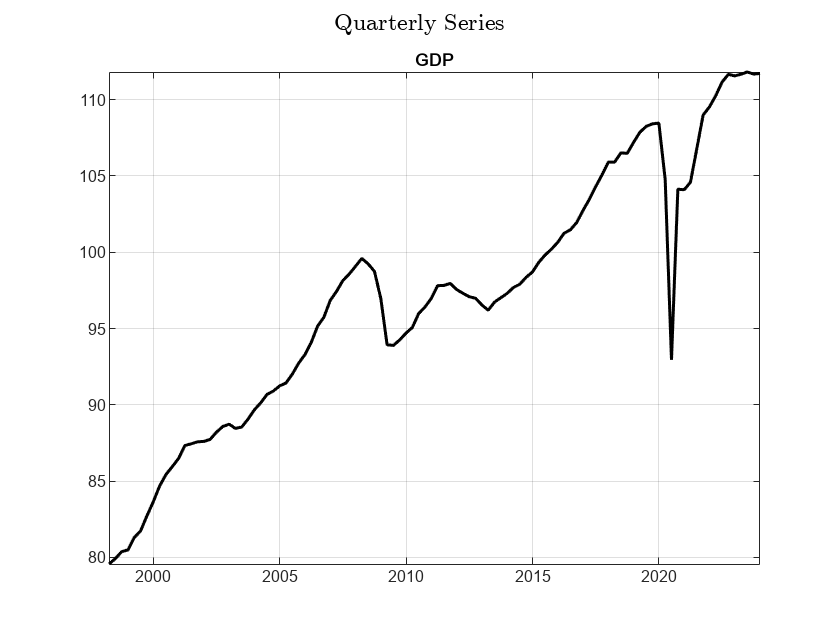

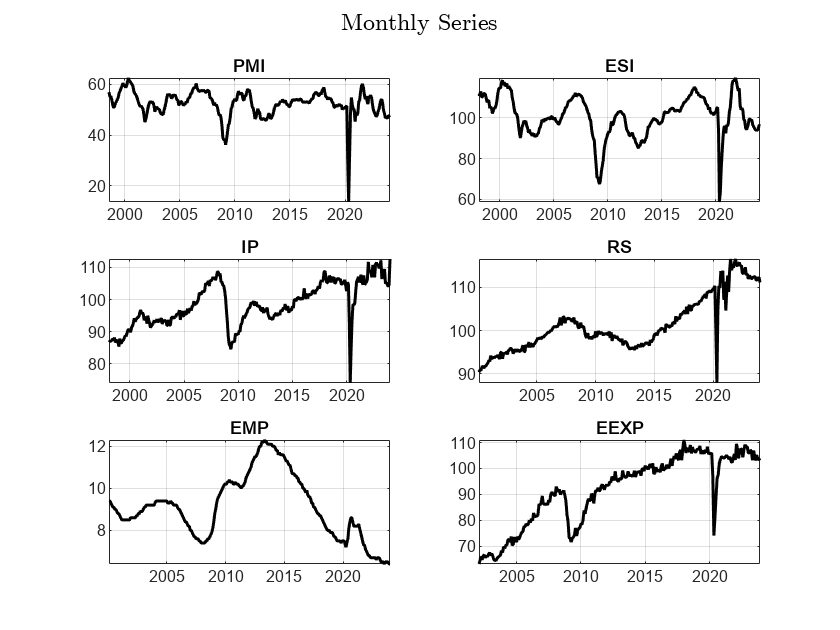

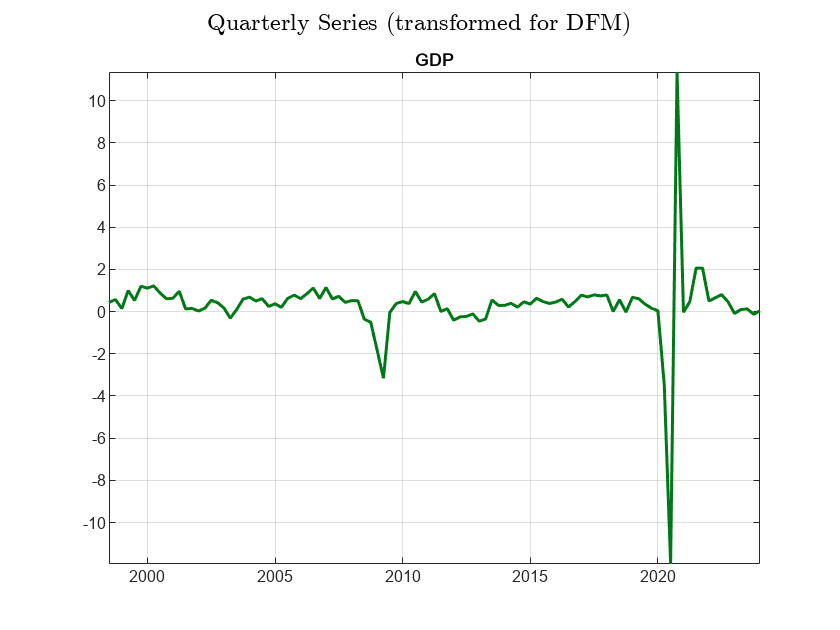

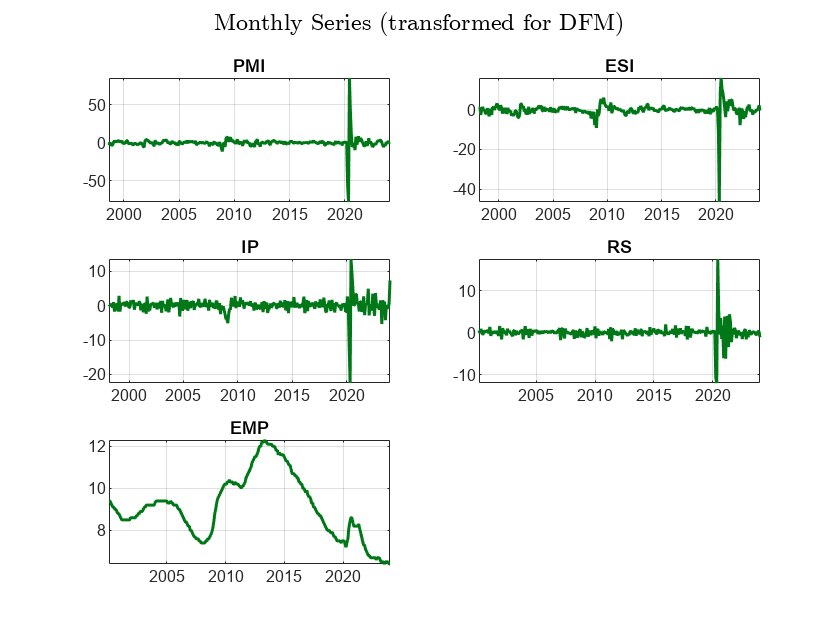

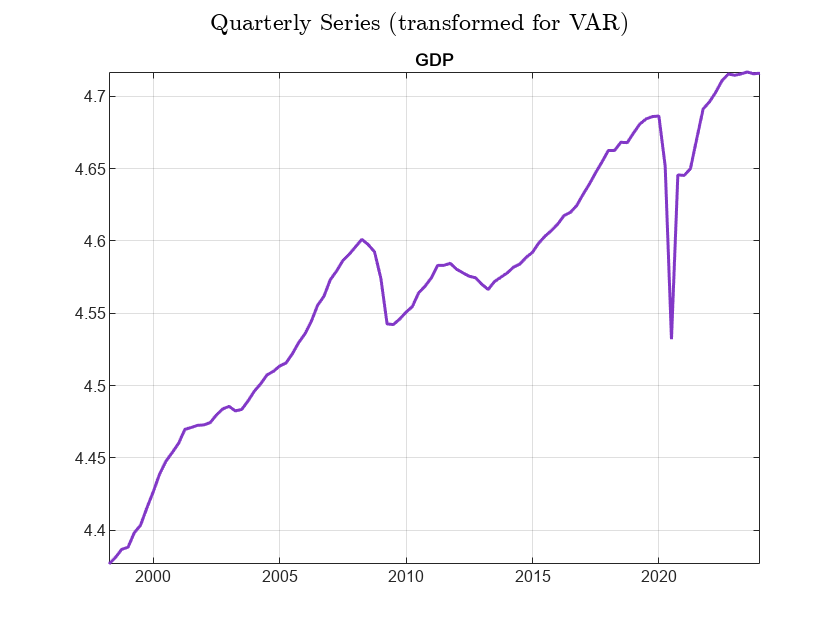

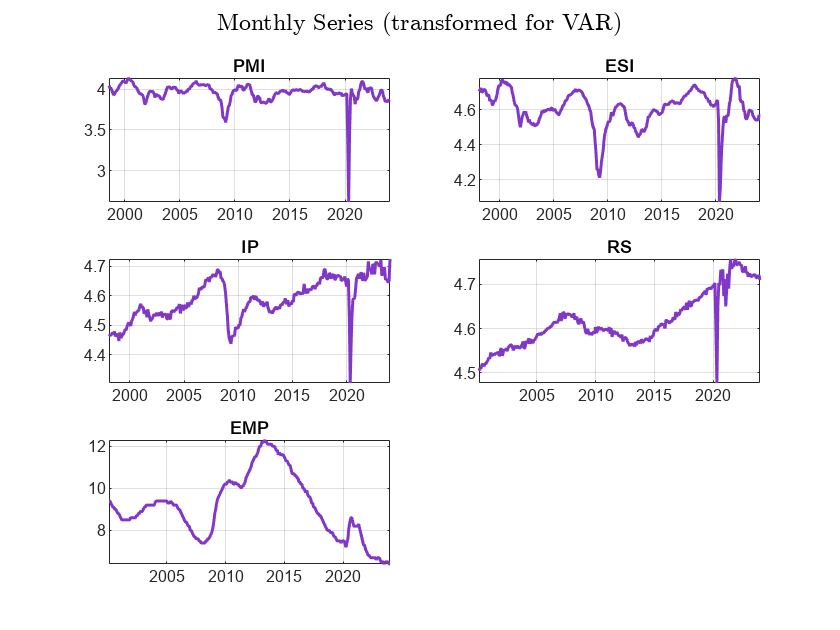

 
% preprocess data
run(fullfile(workpath,'DATA.m'))


% uncomment for no covid in sample
% yraw = yraw(1:end-12*4,:);  
% T = size(yraw,1);
% idx = 1-isnan(yraw);
% dates = dates(1:end-12*4,:);
% run('DATA')

`Model estimation`

`Gibbs sampler draws:`

totDrawsKeep = 800;
totDrawsBurn = 200;
totDraws = totDrawsKeep + totDrawsBurn; 

if totDrawsKeep < totDrawsBurn
    disp('Draws to keep is smaller than draws to burn! You need to keep more draws than you discard...')
end

fprintf('Number of draws to keep: %d \nNumber of draws to burn: %d \nTotal number of draws: %d', totDrawsKeep,totDrawsBurn,totDraws)

Number of draws to keep: 800 
Number of draws to burn: 200 
Total number of draws: 1000

`Estimate DFM:`

 
% estimate DFM
run(fullfile(workpath,'DFM.m'))

 
% plot DFM results
run(fullfile(workpath,'DFM_CHART.m'))

`Estimate VAR:`

 
% estimate VAR
run(fullfile(workpath,'VAR.m'));

Starting Mixed Frequency Bayesian VAR estimation...


 
% plot VAR results
run(fullfile(workpath,'VAR_CHART.m'))

`Comparison analysis wrt ECB projections`

`Enter ECB projections file name:`

% load ECB data
datatableECB = readtable("ECB_projections.xlsx", ReadVariableNames=true);  
fileName = 'ECB_projections.xlsx';
fprintf('File name: %s', fileName)

namesECB = datatableECB.Properties.VariableNames(2:end);
datesECB = table2array(datatableECB(:,1));
dataECB = table2array(datatableECB(:,2:end));


`Slide number of years to go back for forecast charts:`

% specs
years =5;  % quarters back
fprintf('Number of years back: %d', years)

periodsBack = years*4;  % years times quarters
horizonECB = 4*3;  % 3-year forecast horizon of ECB 
datesECBCompare = datesECB(2:end); % match ECB and model dates due to lag for computing growth rates
dataECBCompare = dataECB(2:end,:);  % match ECB and model data due to lag for computing growth rates


`Run comparison:`

 
% compare models wrt ECB projections
run(fullfile(workpath,'COMPARE_ECB.m'));

`Results report`

`Click on "Hide code" on the right of the "Live Editor" file to see results only`

`and build the report (with code chunks):`

 
% save report with code
export('main', fullfile(savepath,'Results_report.html'));
disp('Report done!')